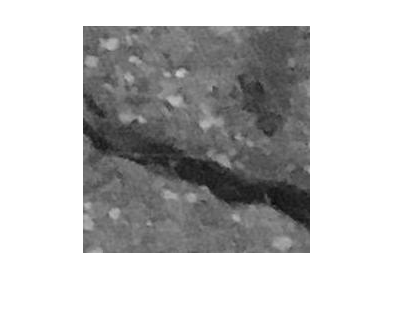

img = imread("00146.jpg");
imgGray = im2gray(img);
imshow(imgGray)

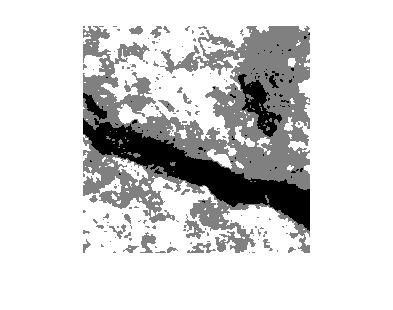


nThresh = 2;
threshValues = multithresh(imgGray, nThresh);

L = imquantize(imgGray, threshValues);

imshow(L, [])

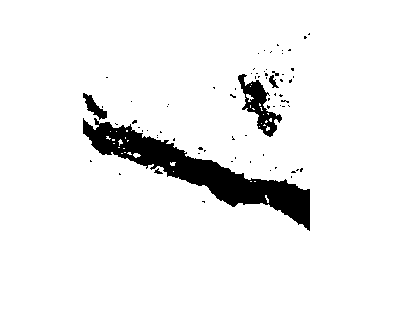

BW = L > 1;
imshow(BW)

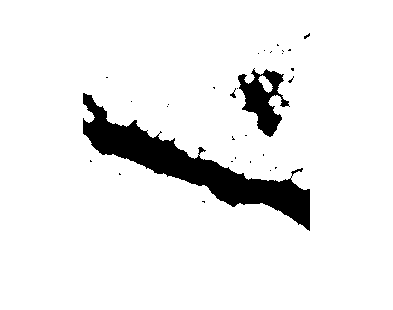


se = strel("disk", 4, 0);
BW = imopen(BW, se);
imshow(BW)

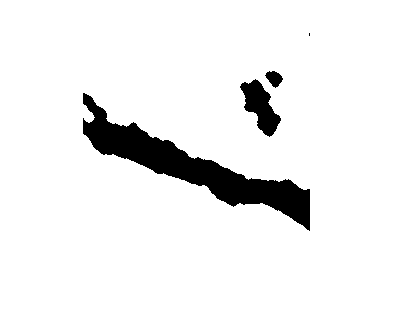


BW = imclose(BW, se);
imshow(BW)

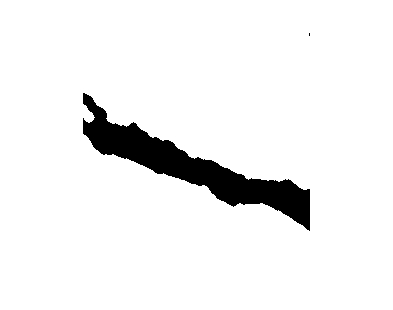


BW = imfill(BW, "holes");
imshow(BW)

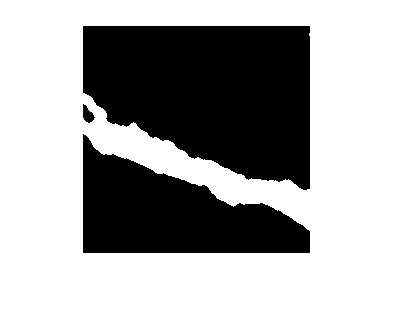


BW = imcomplement(BW);
imshow(BW)

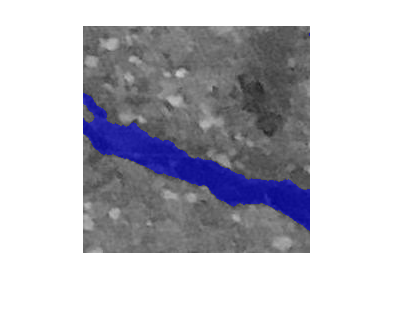


maskOn = labeloverlay(imgGray, BW);
imshow(maskOn)

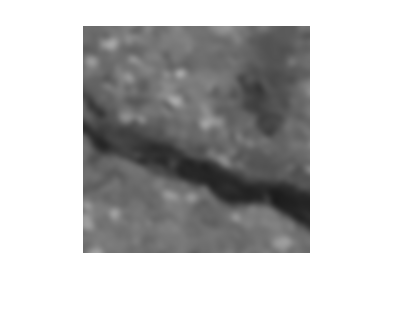

stdev = 3;
IF = imgaussfilt(imgGray, stdev);
imshow(IF)

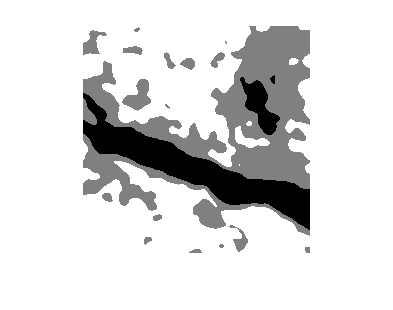

threshValuesIF = multithresh(IF, nThresh);
LF = imquantize(IF, threshValuesIF);

imshow(LF, [])

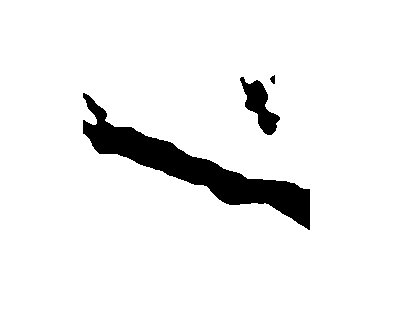

BWF = LF > 1;
imshow(BWF)

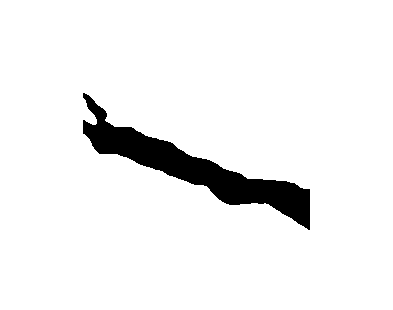


BWF = imfill(BWF, "holes");
imshow(BWF)

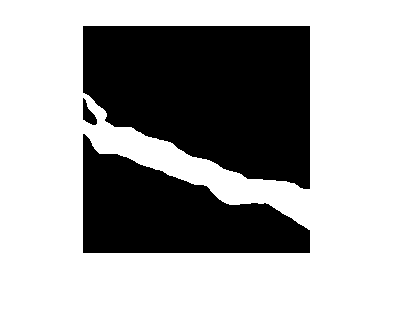


BWF = imcomplement(BWF);
imshow(BWF)

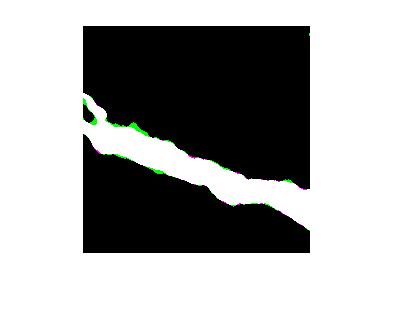

imshowpair(BW,BWF)